disp("Interpolation")

Interpolation


clc; clear;

% Equation
syms A B C Rs n
STeq = 1/(A + B*log(Rs) + C*log(Rs)^n)

$$STeq = \frac{1}{A+C\,{\log\left(\mathrm{Rs}\right)}^{n}+B\,\log\left(\mathrm{Rs}\right)}$$

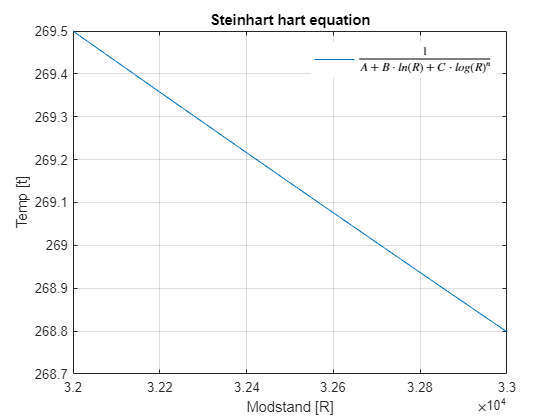

% Plot

A = 5.11*1e-4; 
B = 3.717*1e-4; 
C = -1.278*1e-5;
D = 6.441*1e-7;

n = 3;

Rs = linspace(32000, 33000, 1000);

STeq = 1./(A + B*log(Rs) + C*log(Rs).^(n-1) + D*log(Rs).^n);


plot(Rs, STeq), grid("on")
title("Steinhart hart equation")
legend("$\frac{1}{A + B\cdot ln(R) + C\cdot log(R)^n}$","Interpreter","latex","Box","off")
ylabel("Temp [t]")
xlabel("Modstand [R]")

clc; clear;

data1 = importdata("Log Data 17-04-2023 12.27.24.txt");
data2 = importdata("Log Data 17-04-2023 12.54.19.txt");
data3 = importdata("Log Data 17-04-2023 13.22.15.txt");
data4 = importdata("Log Data 17-04-2023 13.52.30.txt");
data5 = importdata("Log Data 17-04-2023 14.33.43.txt");
data6 = importdata("Log Data 17-04-2023 15.20.19.txt");


A = 5.11*1e-4; 
B = 3.717*1e-4; 
C = -1.278*1e-5;
D = 6.441*1e-7;

n = 3;

Rs = [data1.data(:,2);data2.data(:,2);data3.data(:,2);data4.data(:,2);data5.data(:,2);data6.data(:,2)];

stds = [std(data1.data(:, 2));std(data1.data(:, 2))];

STeq = 1./(A + B*log(Rs) + C*log(Rs).^(n-1) + D*log(Rs).^n) - 273.15;


%scatter(Rs, STeq);




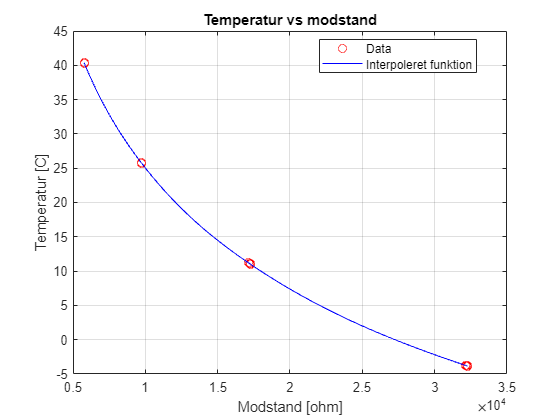

% Linspace til plot
Rslin = linspace(min(Rs), max(Rs), 1000);

% Not a knot spline oprettes
spl_func = spline(Rs,STeq,Rslin);



A = 5.11*1e-4; 
B = 3.717*1e-4; 
C = -1.278*1e-5;
D = 6.441*1e-7;

n = 3;

Rs_model = linspace(min(Rs), max(Rs), 1000);

STeq_model = 1./(A + B*log(Rs_model) + C*log(Rs_model).^(n-1) + D*log(Rs_model).^n) - 273.15;


% Data plottes
plot(Rs,STeq, 'ro', 'DisplayName', 'Data'), grid("on")
title('Temperatur vs modstand')
xlabel('Modstand [ohm]')
ylabel('Temperatur [C]')

% Polyfit
%stein = '1./(A + B*log(x) + C*log(x).^(n-1) + D*log(x).^n) - 273.15';
%newfit = fit(Rs, STeq, stein, 'Start', [A, B, C, D, n]);



hold on

% Fit plottes
plot(Rslin, spl_func,'b', 'DisplayName','Interpoleret funktion')

% Modelligning plottes
%plot(Rs_model,STeq_model,'r','DisplayName','Model Funktion')

% Polyfit plottes
%plot(newfit)

legend('Location','best')

hold off

## Mere dataanalyse

clc; clear;

% Første cyklus
% -5C
ohms1_5 = importdata("Log Data 17-04-2023 12.27.24.txt").data(:, 2)';
% 10
ohms1_10_op = importdata("Log Data 17-04-2023 12.54.19.txt").data(:, 2)';
% 25
ohms1_25_op = importdata("Log Data 17-04-2023 13.22.15.txt").data(:, 2)';
% 40
ohms1_40_op = importdata("Log Data 17-04-2023 13.52.30.txt").data(:, 2)';
% 25
ohms1_25_ned = importdata("Log Data 17-04-2023 14.33.43.txt").data(:, 2)';
% 10
ohms1_10_ned = importdata("Log Data 17-04-2023 15.20.19.txt").data(:, 2)';

% Anden cyklus
% -5C
ohms2_5 = importdata("2. Cyklus\Log Data 17-04-2023 1.txt").data(:, 2)';
% 10
ohms2_10_op = importdata("2. Cyklus\Log Data 17-04-2023 2.txt").data(:, 2)';
% 25
ohms2_25_op = importdata("2. Cyklus\Log Data 17-04-2023 3.txt").data(:, 2)';
% 40
ohms2_40_op = importdata("2. Cyklus\Log Data 17-04-2023 4.txt").data(:, 2)';
% 25
ohms2_25_ned = importdata("2. Cyklus\Log Data 17-04-2023 5.txt").data(:, 2)';
% 10
ohms2_10_ned = importdata("2. Cyklus\Log Data 17-04-2023 6.txt").data(:, 2)';

% Tredje cyklus
% -5C
ohms3_5 = importdata("3. Cyklus\Log Data 17-04-2023 20.05.37.txt").data(:, 2)';
% 10
ohms3_10_op = importdata("3. Cyklus\Log Data 17-04-2023 20.34.42.txt").data(:, 2)';
% 25
ohms3_25_op = importdata("3. Cyklus\Log Data 17-04-2023 21.02.25.txt").data(:, 2)';
% 40
ohms3_40_op = importdata("3. Cyklus\Log Data 17-04-2023 21.34.34.txt").data(:, 2)';
% 25
ohms3_25_ned = importdata("3. Cyklus\Log Data 17-04-2023 22.33.53.txt").data(:, 2)';
% 10
ohms3_10_ned = importdata("3. Cyklus\Log Data 18-04-2023 08.48.40.txt").data(:, 2)';


% Samlet data
ohm5 = [ohms1_5; ohms2_5; ohms3_5];

ohm10s_op = [ohms1_10_op; ohms2_10_op;ohms3_10_op];
ohm10s_ned = [ohms1_10_ned; ohms2_10_ned; ohms3_10_ned];

ohm25s_op = [ohms1_25_op; ohms2_25_op;ohms3_25_op]; 
ohm25s_ned = [ohms1_25_ned; ohms2_25_ned; ohms3_25_ned];

ohm40 = [ohms1_40_op;ohms2_40_op;ohms3_40_op]

ohm40 = 1.0e+03 *

    5.7698    5.7749    5.7716    5.7692    5.7734    5.7758    5.7733    5.7658    5.7722    5.7729    5.7732    5.7701    5.7722    5.7774    5.7712    5.7666    5.7713    5.7740    5.7739    5.7777    5.7736    5.7726    5.7718    5.7748    5.7690    5.7699    5.7721    5.7678    5.7728    5.7763
    5.7704    5.7728    5.7721    5.7696    5.7696    5.7724    5.7721    5.7727    5.7738    5.7730    5.7714    5.7741    5.7754    5.7757    5.7763    5.7740    5.7717    5.7729    5.7720    5.7737    5.7757    5.7735    5.7736    5.7754    5.7789    5.7715    5.7699    5.7716    5.7748    5.7722
    5.7787    5.7688    5.7742    5.7678    5.7662    5.7666    5.7676    5.7692    5.7697    5.7710    5.7698    5.7642    5.7676    5.7675    5.7691    5.7722    5.7674    5.7693    5.7663    5.7667    5.7679    5.7708    5.7693    5.7690    5.7688    5.7672    5.7652    5.7712    5.7666    5.7573


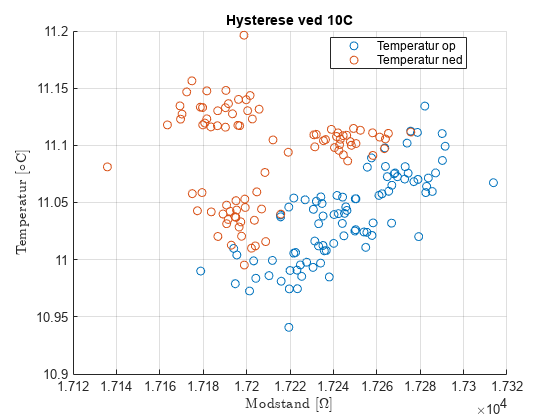


% Steinhart Hart ligning
A = 5.11*1e-4; 
B = 3.717*1e-4; 
C = -1.278*1e-5;
D = 6.441*1e-7;

n = 3;

loops = size(ohm10s_ned,2);
k = size(ohm10s_op,1);

%Rs = ohms1_10_op;

% Temperature
Ts_5 = zeros(k,length(ohm5));

Ts_10_op = zeros(k,length(ohm10s_op));
Ts_10_ned = zeros(k,length(ohm10s_ned));

Ts_25_op = zeros(k,length(ohm25s_op));
Ts_25_ned = zeros(k,length(ohm25s_ned));

Ts_40 = zeros(k,length(ohm40));

STeq = @(rs) 1./(A + B*log(rs) + C*log(rs).^(n-1) + D*log(rs).^n) - 273.15;

for j = 1:k
    for i = 1:loops
        Ts_5(j,i) = STeq(ohm5(j,i));

        Ts_10_op(j,i) = STeq(ohm10s_op(j,i));
        Ts_10_ned(j,i) = STeq(ohm10s_ned(j,i));

        Ts_25_op(j,i) = STeq(ohm25s_op(j,i));
        Ts_25_ned(j,i) = STeq(ohm25s_ned(j,i));

        Ts_40(j,i) = STeq(ohm40(j,i));
    end
end

%--------------------------------%
%---------- 10 grader -----------%
%--------------------------------%


ts10_op_alle = sort([Ts_10_op(1, :),Ts_10_op(2, :),Ts_10_op(3, :)]);
ts10_ned_alle = sort([Ts_10_ned(1, :),Ts_10_ned(2, :),Ts_10_ned(3, :)]);

ohm10s_op_alle = [ohms1_10_op, ohms2_10_op, ohms3_10_op]; 
ohm10s_ned_alle = [ohms1_10_ned, ohms2_10_ned, ohms3_10_ned];

scatter(ohm10s_op_alle, ts10_op_alle, "DisplayName","Temperatur op")
grid("on")

hold on

scatter(ohm10s_ned_alle, ts10_ned_alle, "DisplayName","Temperatur ned")

title("Hysterese ved 10C")
legend("show", "location", "best")
xlabel("Modstand [$\Omega$]","Interpreter","latex")
ylabel("Temperatur [$\circ$C]", "Interpreter","latex")

hold off
saveas(gcf,"hysterese10C.png")


fejl10C = max(abs([Ts_10_op(1, :),Ts_10_op(2, :),Ts_10_op(3, :)] - [Ts_10_ned(1, :),Ts_10_ned(2, :),Ts_10_ned(3, :)]))

fejl10C = 0.1908

fejl25C = max(abs([Ts_25_op(1, :),Ts_25_op(2, :),Ts_25_op(3, :)] - [Ts_25_ned(1, :),Ts_25_ned(2, :),Ts_25_ned(3, :)]))

fejl25C = 0.1059

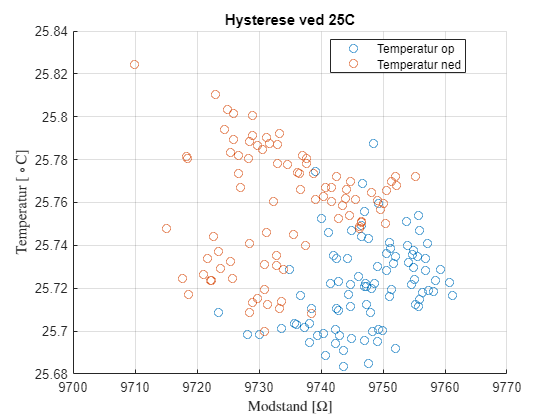


%--------------------------------%
%---------- 25 grader -----------%
%--------------------------------%

ts25_op_alle = sort([Ts_25_op(1, :),Ts_25_op(2, :),Ts_25_op(3, :)]);
ts25_ned_alle = sort([Ts_25_ned(1, :),Ts_25_ned(2, :),Ts_25_ned(3, :)]);

ohm25s_op_alle = [ohms1_25_op, ohms2_25_op, ohms3_25_op]; 
ohm25s_ned_alle = [ohms1_25_ned, ohms2_25_ned, ohms3_25_ned];

scatter(ohm25s_op_alle, ts25_op_alle, "DisplayName","Temperatur op")
grid("on")

hold on

scatter(ohm25s_ned_alle, ts25_ned_alle, "DisplayName","Temperatur ned")

title("Hysterese ved 25C")
legend("show", "location", "best")
xlabel("Modstand [$\Omega$]","Interpreter","latex")
ylabel("Temperatur [$\circ$C]", "Interpreter","latex")

hold off
saveas(gcf,"hysterese25C.png")


data = ts10_op_alle;
data2= ts10_ned_alle;

mean10op = mean(ts10_op_alle)

mean10op = 11.0379

mean10ned = mean(ts10_ned_alle)

mean10ned = 11.0916

Frihedsgradernes formel


$$\mathrm{df}=n_{1}+n_{2}-2$$

-----------------------------------------------------------------
Stikprøvemiddelværdiernes formel


$$\bar{y}=\frac{\Sigma \,y_{i}}{3}$$

-----------------------------------------------------------------
Stikprøvevariansernes formel


$$s=\frac{3\,\left(\Sigma \left({y_{i}}^{2}\right)-{\Sigma \left(y_{i}\right)}^{2}\right)}{3\,\left(3-1\right)}$$

-----------------------------------------------------------------
Pooled standardafvigelsens formel


$$s_{p}=\sqrt{\frac{\left(n_{1}-1\right)\,{s_{1}}^{2}+\left(n_{2}-1\right)\,{s_{2}}^{2}}{n_{1}+n_{2}-2}}$$

-----------------------------------------------------------------
t-værdiens formel


$$\frac{t_{\mathrm{df},\alpha }}{2}=-\mathrm{tinv}\,\frac{\alpha }{2}\,\mathrm{df}$$

-----------------------------------------------------------------
Teststørrelsens formel


$$t_{\mathrm{val}}=\frac{y_{\mathrm{bar1}}-y_{\mathrm{bar2}}-\delta }{s_{p}\,\sqrt{\frac{1}{n_{1}}\,\frac{1}{n_{2}}}}$$

-----------------------------------------------------------------
    Datanavne    Middelværdier    Spredning    standardafv.    Datapunkter
    _________    _____________    _________    ____________    ___________

    "Input 1"       11.038        0.0015011      0.038743          90     
    "Input 2"       11.092        0.0017975      0.042397          90     

    Frihedsgrader    Pooled varians    Pooled spredning    Teststatistik      t0       p-værdi      h-værdi
    _____________    ______________    ________________    _____________    ______    __________    _______

       

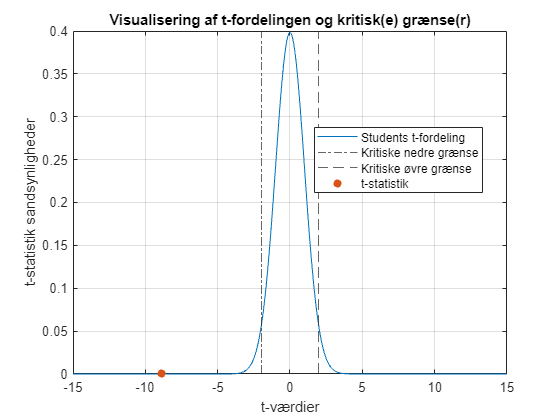

Da h = 1 forkastes nulhypotesen
Ydermere ses det også at t-værdien -8.8797 overstiger den kritiske grænse på 1.9734


ans = struct with fields:
    stats: [1×1 struct]
        p: 7.1319e-16
       ci: [-0.0674 -0.0401]



ttest2popMiddelInd(data,data2, "both",95,0)

Da populations-standardafvigelsen er kendt, vides det pr. den
centrale grænseværdi sætning at stikprøven er standard normalfordelt
Først regnes stikprøvemiddelværdien


$$\bar{y}=\frac{\Sigma \,y_{i}}{3}$$

y_bar_x = 11.0916

Z værdien skal findes, vha. følgende formel


$$\frac{z_{\alpha }}{2}=\mathrm{norminv}\,\frac{\alpha }{2}$$

test_vals =    -1.9600
    1.9600


$$\mathrm{Upper}=\bar{y}+\frac{\frac{z_{\alpha }}{2}\,\sigma }{\sqrt{3}}$$

upper_t = 11.0829

$$\mathrm{Lower}=\bar{y}-\frac{\frac{z_{\alpha }}{2}\,\sigma }{\sqrt{3}}$$

lower_t = 11.1004

Teststørrelsen udregnes, til sammenligning


$$z=\bar{y}-\frac{\mu_{0}}{\sigma \,\sqrt{3}}$$

    Interval    Værdier    Test type    Testværdier     Værdi     Deskriptorer
    ________    _______    _________    ___________    _______    ____________

    "Nedre"     11.083     "Z nedre"       -1.96       "y_bar"        11.092  
    "Øvre"        11.1     " Z øvre"        1.96       "sigma"      0.042397  



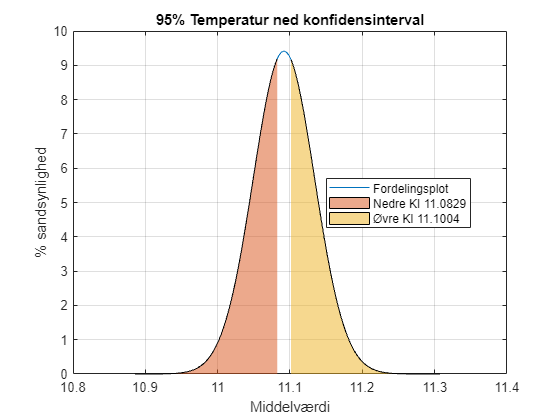

ss=std(data2);
mm=mean(data2);
KonfidensIntervalNormal(data2, 95, ss,mm)

Da populations-standardafvigelsen er kendt, vides det pr. den
centrale grænseværdi sætning at stikprøven er standard normalfordelt
Først regnes stikprøvemiddelværdien


$$\bar{y}=\frac{\Sigma \,y_{i}}{3}$$

y_bar_x = 11.0379

Z værdien skal findes, vha. følgende formel


$$\frac{z_{\alpha }}{2}=\mathrm{norminv}\,\frac{\alpha }{2}$$

test_vals =    -1.9600
    1.9600


$$\mathrm{Upper}=\bar{y}+\frac{\frac{z_{\alpha }}{2}\,\sigma }{\sqrt{3}}$$

upper_t = 11.0299

$$\mathrm{Lower}=\bar{y}-\frac{\frac{z_{\alpha }}{2}\,\sigma }{\sqrt{3}}$$

lower_t = 11.0459

Teststørrelsen udregnes, til sammenligning


$$z=\bar{y}-\frac{\mu_{0}}{\sigma \,\sqrt{3}}$$

    Interval    Værdier    Test type    Testværdier     Værdi     Deskriptorer
    ________    _______    _________    ___________    _______    ____________

    "Nedre"      11.03     "Z nedre"       -1.96       "y_bar"        11.038  
    "Øvre"      11.046     " Z øvre"        1.96       "sigma"      0.038743  



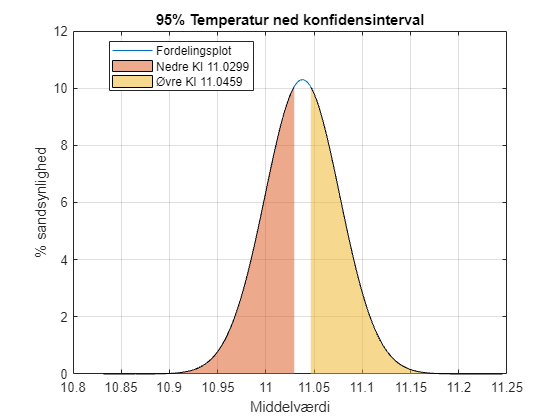


ss1=std(data);
mm1=mean(data);
KonfidensIntervalNormal(data, 95, ss1,mm1)

% Standardafvigelser
s5 = zeros(3,1);
s10op = zeros(3,1);
s10ned = zeros(3,1);
s25op = zeros(3,1);
s25ned = zeros(3,1);
s40 = zeros(3,1);


for h = 1:3
    s5(h)=std(Ts_5(h,:));

    s10op(h)=std(Ts_10_op(h,:));
    s10ned(h)=std(Ts_10_ned(h,:));

    s25op(h)=std(Ts_25_op(h,:));
    s25ned(h)=std(Ts_25_ned(h,:));

    s40(h)=std(Ts_40(h,:));
    
end

% Middel standard afvigelser

% s5 = mean(s5);
% s10op = mean(s10op);
% s10ned = mean(s10ned);
% s25op = mean(s25op);
% s25ned = mean(s25ned);
% s40 = mean(s40);
s5 = max(s5);
s10op = max(s10op);
s10ned = max(s10ned);
s25op = max(s25op);
s25ned = max(s25ned);
s40 = max(s40);

% Middel spændinger
mohm5 = mean(ohm5(:));
mohm10op = mean(ohm10s_op(:));
mohm10ned = mean(ohm10s_ned(:));

mohm25op = mean(ohm25s_op(:));
mohm25ned = mean(ohm25s_ned(:));

mohm40 = mean(ohm40(:));

meanohms_op = [mohm5,mohm10op,mohm25op,mohm40];
meanohms_ned = [mohm5,mohm10ned,mohm25ned,mohm40];


% Til plot for op data

meanstds_op = [s5,s10op,s25op,s40];
meanstds_ned = [s5,s10ned,s25ned,s40];

%scatter(meanohms_op,meanstds_op, "DisplayName","Afvigelsespunkter")




mdl_op = fitlm(meanohms_op,meanstds_op,"quadratic")

mdl_op = Linear regression model:
    y ~ 1 + x1 + x1^2

Estimated Coefficients:
                    Estimate          SE         tStat      pValue 
                   ___________    __________    _______    ________

    (Intercept)       0.033864     0.0077442     4.3728     0.14312
    x1             -3.5629e-06    1.0263e-06    -3.4717     0.17854
    x1^2            1.7867e-10    2.5948e-11     6.8856    0.091815


Number of observations: 4, Error degrees of freedom: 1
Root Mean Squared Error: 0.00366
R-squared: 0.997,  Adjusted R-Squared: 0.992
F-statistic vs. constant model: 198, p-value = 0.0502

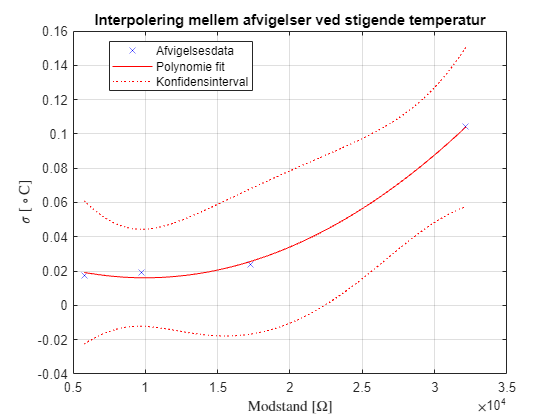



% Linspace til plot
meanlin = linspace(min(meanohms_op), max(meanohms_op), 1000);


%plot(stdfit_op)
plot(mdl_op)
grid("on")
xlabel('Modstand [$\Omega$]',"Interpreter","latex")
ylabel('$\sigma$ [$\circ$C]',"Interpreter","latex")
title("Interpolering mellem afvigelser ved stigende temperatur")
legend("Afvigelsesdata","Polynomie fit","Konfidensinterval","location","best")

saveas(gcf,"StigendeAfvigelseInterpol.png")


% Til plot for ned data

%scatter(meanohms_ned,meanstds_ned, "DisplayName","Afvigelsespunkter")

mdl_ned = fitlm(meanohms_ned,meanstds_ned,"quadratic")

mdl_ned = Linear regression model:
    y ~ 1 + x1 + x1^2

Estimated Coefficients:
                    Estimate          SE         tStat      pValue 
                   ___________    __________    _______    ________

    (Intercept)       0.037533     0.0087577     4.2857     0.14593
    x1             -4.2679e-06    1.1611e-06    -3.6756     0.16911
    x1^2            1.9702e-10    2.9355e-11     6.7116    0.094161


Number of observations: 4, Error degrees of freedom: 1
Root Mean Squared Error: 0.00414
R-squared: 0.997,  Adjusted R-Squared: 0.991
F-statistic vs. constant model: 160, p-value = 0.0558

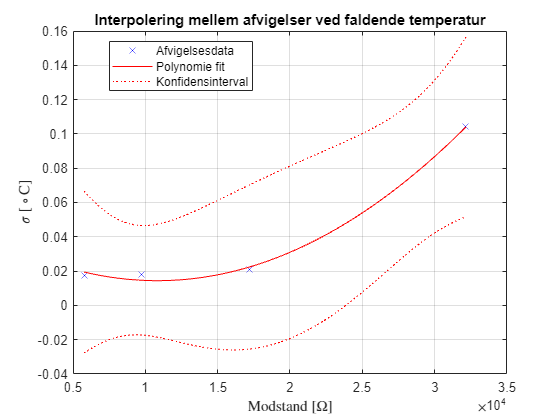




% Linspace til plot



plot(mdl_ned)
grid("on")
title("Interpolering mellem afvigelser ved faldende temperatur")
xlabel('Modstand [$\Omega$]',"Interpreter","latex")
ylabel('$\sigma$ [$\circ$C]',"Interpreter","latex")
legend("Afvigelsesdata","Polynomie fit","Konfidensinterval","location","best")

saveas(gcf,"FaldendeAfvigelseInterpol.png")

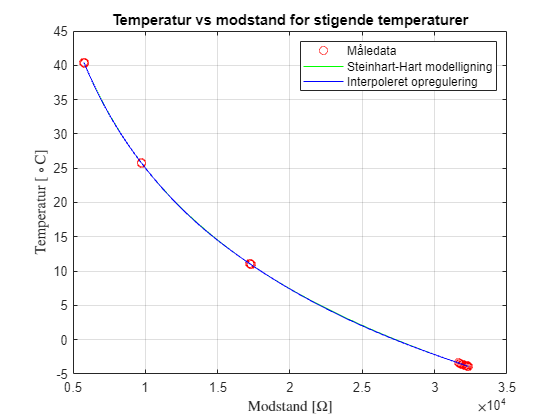



% Samlet data
ohm5 = [ohms1_5, ohms2_5, ohms3_5];

ohm10s_op = [ohms1_10_op, ohms2_10_op, ohms3_10_op];
ohm10s_ned = [ohms1_10_ned, ohms2_10_ned, ohms3_10_ned];

ohm25s_op = [ohms1_25_op, ohms2_25_op, ohms3_25_op]; 
ohm25s_ned = [ohms1_25_ned, ohms2_25_ned, ohms3_25_ned];

ohm40 = [ohms1_40_op, ohms2_40_op, ohms3_40_op];

Rs_op = [ohm5, ohm10s_op, ohm25s_op, ohm40];
Rs_ned = [ohm5, ohm10s_ned, ohm25s_ned, ohm40];

% Steinhart hart

A = 5.11*1e-4; 
B = 3.717*1e-4; 
C = -1.278*1e-5;
D = 6.441*1e-7;


n = 3;


STeq_op = 1./(A + B*log(Rs_op) + C*log(Rs_op).^(n-1) + D*log(Rs_op).^n) - 273.15;
STeq_ned = 1./(A + B*log(Rs_ned) + C*log(Rs_ned).^(n-1) + D*log(Rs_ned).^n) - 273.15;

% Linspace til plot
Rslin_op = linspace(min(Rs_op), max(Rs_op), 360);
Rslin_ned = linspace(min(Rs_ned), max(Rs_ned), 360);

% Not a knot spline oprettes
spl_func_op = spline(Rs_op,STeq_op,Rslin_op);
spl_func_ned = spline(Rs_ned,STeq_ned,Rslin_ned);

% Model Funktion


Rs_model_op = linspace(min(Rs_op)*1, max(Rs_op)*1, 360);

STeq_model_op = 1./(A + B*log(Rs_model_op) + C*log(Rs_model_op).^(n-1) + D*log(Rs_model_op).^n) - 273.15;

Rs_model_ned = linspace(min(Rs_ned)*1, max(Rs_ned)*1, 360);

STeq_model_ned = 1./(A + B*log(Rs_model_ned) + C*log(Rs_model_ned).^(n-1) + D*log(Rs_model_ned).^n) - 273.15;




% Data plottes for op regulering
plot(Rs_op,STeq_op, 'ro', 'DisplayName', 'Måledata'), grid("on")
title('Temperatur vs modstand for stigende temperaturer')
xlabel('Modstand [$\Omega$]',"Interpreter","latex")
ylabel('Temperatur [$\circ$C]',"Interpreter","latex")


hold on

% Moddelligning op plottes
plot(Rs_model_op,STeq_model_op, 'g',"DisplayName","Steinhart-Hart modelligning")


% Fit plottes
plot(Rslin_op, spl_func_op,'b', 'DisplayName','Interpoleret opregulering')

legend('Location','best')

hold off
saveas(gcf,"TempModstandStigende.png")

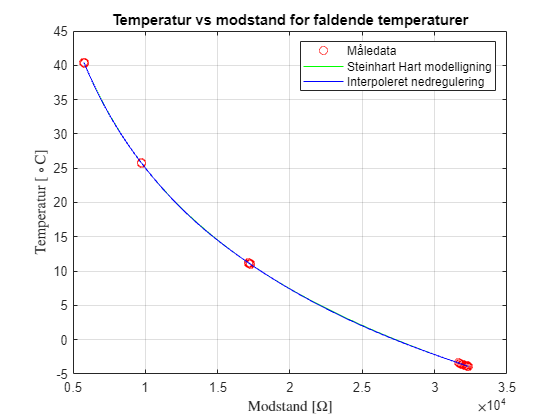


% Data plottes for ned regulering
plot(Rs_ned,STeq_ned, 'ro', 'DisplayName', 'Måledata'), grid("on")
title('Temperatur vs modstand for faldende temperaturer')
xlabel('Modstand [$\Omega$]',"Interpreter","latex")
ylabel('Temperatur [$\circ$C]',"Interpreter","latex")


hold on

% Modelligning plottes
plot(Rs_model_ned,STeq_model_ned, 'g',"DisplayName","Steinhart Hart modelligning")


% Fit plottes
plot(Rslin_ned, spl_func_ned,'b', 'DisplayName','Interpoleret nedregulering')

legend('Location','best')

hold off
saveas(gcf,"TempModstandFaldende.png")


OpForskel = STeq_model_op - spl_func_op;
NedForskel = STeq_model_ned - spl_func_ned;
maxop = max(abs(OpForskel))

maxop = 0.0634

maxned = max(abs(NedForskel))

maxned = 0.0643

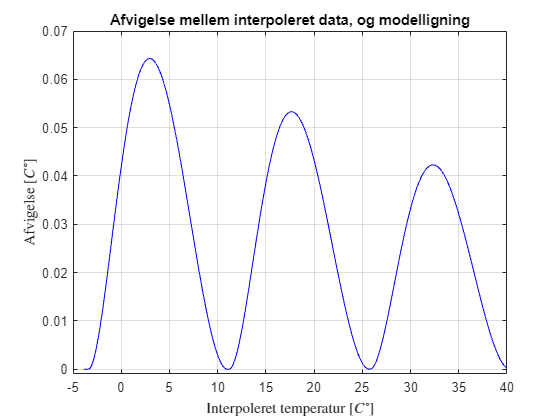


plot(spl_func_ned,NedForskel, "b","DisplayName","Afvigelse ned")
grid("on")
title("Afvigelse mellem interpoleret data, og modelligning")
ylabel("Afvigelse [$C^\circ$]","Interpreter","latex")
xlabel("Interpoleret temperatur [$C^\circ$]","Interpreter","latex")
xlim([-5,40]),ylim([-0.001,0.07])




% 
% 
% %--------------------------%
% %------ Errorbarplot ------%
% %--------------------------%
% 
% 
% % Linspace til plot
% Rslin_op = linspace(min(Rs_op), max(Rs_op), 200);
% Rslin_ned = linspace(min(Rs_ned), max(Rs_ned), 200);
% 
% % Not a knot spline oprettes
% spl_func_op = spline(Rs_op,STeq_op,Rslin_op);
% spl_func_ned = spline(Rs_ned,STeq_ned,Rslin_ned);
% 
% % erros
% errs_op = mdl_op(Rslin_op);
% errs_ned = mdl_ned(Rslin_ned);
% 
% errorbar(Rslin_ned, spl_func_ned, errs_ned, "MarkerSize",18)
% grid("minor")
% ylim([9.5,10.5])
% xlim([1.75,1.85]*1e4)
% 
% title("Afskåret errorbarplot for faldende temperatur")
% xlabel('Modstand [$\Omega$]',"Interpreter","latex")
% ylabel('Temperatur [$\circ$C]',"Interpreter","latex")
% 
% saveas(gcf, "errorbarplot.png")






% 
% % Samlet data
% ohm5 = [ohms1_5, ohms2_5, ohms3_5];
% 
% ohm10s_op = [ohms1_10_op, ohms2_10_op, ohms3_10_op];
% ohm10s_ned = [ohms1_10_ned, ohms2_10_ned, ohms3_10_ned];
% 
% ohm25s_op = [ohms1_25_op, ohms2_25_op, ohms3_25_op]; 
% ohm25s_ned = [ohms1_25_ned, ohms2_25_ned, ohms3_25_ned];
% 
% ohm40 = [ohms1_40_op, ohms2_40_op, ohms3_40_op];
% 
% Rs_op = [ohm5, ohm10s_op, ohm25s_op, ohm40];
% Rs_ned = [ohm5, ohm10s_ned, ohm25s_ned, ohm40];
% 
% 
% subplot(2,3,1)
% normplot(ohm5)
% title("$5^\circ$C","Interpreter","latex")
% xlabel("Modstand [$\Omega$]","Interpreter","latex")
% 
% subplot(2,3,4)
% normplot(ohm40)
% title("$40^\circ$C","Interpreter","latex")
% xlabel("Modstand [$\Omega$]","Interpreter","latex")
% 
% subplot(2,3,2)
% normplot(ohm10s_op)
% title("$10^\circ$C stigende","Interpreter","latex")
% xlabel("Modstand [$\Omega$]","Interpreter","latex")
% 
% subplot(2,3,5)
% normplot(ohm10s_ned)
% title("$10^\circ$C faldende","Interpreter","latex")
% xlabel("Modstand [$\Omega$]","Interpreter","latex")
% 
% subplot(2,3,3)
% normplot(ohm25s_op)
% title("$25^\circ$C stigende","Interpreter","latex")
% xlabel("Modstand [$\Omega$]","Interpreter","latex")
% 
% subplot(2,3,6)
% normplot(ohm25s_ned)
% title("$25^\circ$C faldende","Interpreter","latex")
% xlabel("Modstand [$\Omega$]","Interpreter","latex")
% 
% saveas(gcf,"normplotafdata.png")

